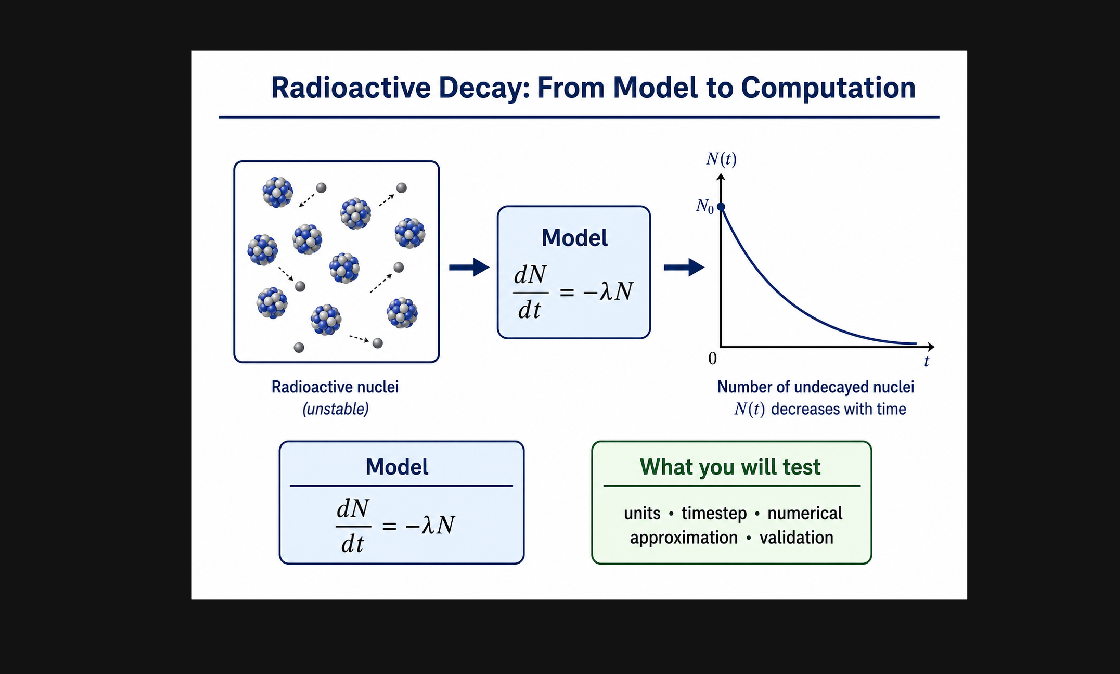

     N0     T_half_h    tMax_h    dt_h    lambda_per_h    lambdaDt
    ____    ________    ______    ____    ____________    ________

    1000       6          24      0.5       0.11552       0.057762



    steps    gridFinal_h    requestedFinal_h
    _____    ___________    ________________

     48          24                24       



Question 6 is still open: complete the Forward Euler loop.


Questions 7 and 8 are waiting for your completed Euler result.


    dt_h    lambdaDt
    ____    ________

      2      0.23105
      1      0.11552
    0.5     0.057762
    0.1     0.011552



clearvars
format shortG
N0 = 1000;                 % initial amount, nuclei or arbitrary amount
T_half_h = 6.0;            % half-life, h
tMax_h = 24.0;             % final time, h
dt_h = 0.5;                % proposed Euler timestep, h
lambda_per_h = log(2)/T_half_h;  % decay constant, 1/h
lambdaDt = lambda_per_h*dt_h;    % dimensionless timestep
parameterRecord = table(N0,T_half_h,tMax_h,dt_h,lambda_per_h,lambdaDt);
disp(parameterRecord)
t_h = 0:dt_h:tMax_h;
N_exact = N0*exp(-lambda_per_h*t_h);
stepCount = numel(t_h) - 1;
disp(table(stepCount,t_h(end),tMax_h,'VariableNames',{'steps','gridFinal_h','requestedFinal_h'}))
assert(abs(t_h(end)-tMax_h) < 100*eps(max(1,tMax_h)), ...
    'The time grid does not reach tMax_h exactly.')
N_euler = nan(size(t_h));
N_euler(1) = N0;
% TODO Question 6: write the Forward Euler loop here.
% Example structure to complete: for k = 1:numel(t_h)-1 ... end
if any(isnan(N_euler))
    disp('Question 6 is still open: complete the Forward Euler loop.')
else
    figure('Name','Euler and exact reference')
    plot(t_h,N_euler/N0,'o-',t_h,N_exact/N0,'k-','LineWidth',1.4)
    grid on
    xlabel('Time, t (h)')
    ylabel('Fraction remaining, N/N_0')
    title('Forward Euler and exact reference')
    legend('Forward Euler','Exact reference','Location','northeast')
end
if any(isnan(N_euler))
    disp('Questions 7 and 8 are waiting for your completed Euler result.')
else
    finalRelativeError = abs(N_euler(end)-N_exact(end))/abs(N_exact(end));
    maxRelativeError = max(abs(N_euler-N_exact)./max(abs(N_exact),eps));
    disp(table(finalRelativeError,maxRelativeError,'VariableNames', ...
        {'finalRelativeError','maxRelativeError'}))
    assert(all(isfinite(N_euler)),'The numerical result is not finite.')
    assert(all(N_euler >= 0),'The numerical result is not physically admissible.')
end
dtValues_h = [2.0 1.0 0.5 0.1];
convergenceTable = table(dtValues_h(:),lambda_per_h*dtValues_h(:), ...
    'VariableNames',{'dt_h','lambdaDt'});
% TODO Question 9: add your loop, error columns, validation check, and labelled plot.
disp(convergenceTable)